In =      1     0     0
     0     1     0
     0     0     1


$$A = \left(\begin{array}{ccc} 0 & 1 & 0\\ \frac{K\,{X_{3}}^{2}}{M\,{X_{1}}^{2}} & 0 & -\frac{2\,K\,X_{3}}{M\,X_{1}}\\ 0 & 0 & -\frac{R}{L} \end{array}\right)$$

$$B = \left(\begin{array}{c} 0\\ 0\\ \frac{1}{L} \end{array}\right)$$

C =      1     0     0


$$H = \frac{2\,K\,X_{1}\,X_{3}}{\left(R+L\,s\right)\,\left(K\,{X_{3}}^{2}-M\,{X_{1}}^{2}\,s^{2}\right)}$$

$$x1 = \frac{K\,V^{2}}{G\,M\,R^{2}}$$

x2 = 0

$$x3 = \frac{V}{R}$$

v1 = 93.5000

v2 = 126.5000

$$Aq = \left(\begin{array}{ccc} 0 & 1 & 0\\ \frac{G^{2}\,M\,R^{2}}{K\,V^{2}} & 0 & -\frac{2\,G\,R}{V}\\ 0 & 0 & -\frac{R}{L} \end{array}\right)$$

$$Aqq = \left(\begin{array}{ccc} 0 & 1 & 0\\ \frac{1578948764266457739237997412352}{223378541517576611328125\,V^{2}} & 0 & -\frac{271737}{500\,V}\\ 0 & 0 & -\frac{554}{13} \end{array}\right)$$

$$Aqq = \left(\begin{array}{cccc} 0 & -1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & \frac{1578948764266457739237997412352}{223378541517576611328125\,V^{2}} & 0 & -\frac{271737}{500\,V}\\ 0 & 0 & 0 & -\frac{554}{13} \end{array}\right)$$

$$B = \left(\begin{array}{c} 0\\ 0\\ 0\\ \frac{1}{L} \end{array}\right)$$

$$B = \left(\begin{array}{c} 0\\ 0\\ 0\\ \frac{20}{13} \end{array}\right)$$

$$q1 = \frac{1578948764266457739237997412352}{223378541517576611328125\,V^{2}}$$

$$q2 = -\frac{271737}{500\,V}$$

$$q3 = -\frac{554}{13}$$

$$q4 = \frac{20}{13}$$

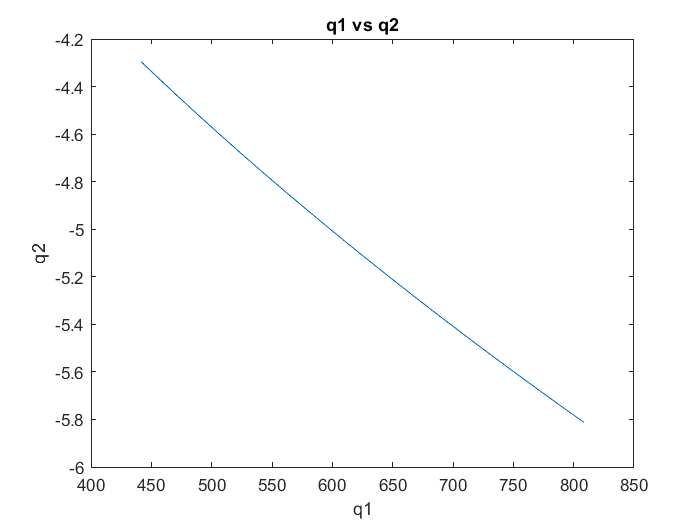

$$A1 = \left(\begin{array}{cccc} 0 & -1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & \frac{6315795057065830956951989649408}{7811324218328136521533203125} & 0 & -\frac{271737}{46750}\\ 0 & 0 & 0 & -\frac{554}{13} \end{array}\right)$$

$$A2 = \left(\begin{array}{cccc} 0 & -1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & \frac{6315795057065830956951989649408}{14298237063998561314501953125} & 0 & -\frac{271737}{63250}\\ 0 & 0 & 0 & -\frac{554}{13} \end{array}\right)$$


 Solver for LMI feasibility problems L(x) < R(x)
    This solver minimizes  t  subject to  L(x) < R(x) + t*I
    The best value of t should be negative for feasibility

 Iteration   :    Best value of t so far 
 
     1                        0.083581
     2                        0.014259
     3                        0.014259
     4                    2.322685e-03
     5                    2.322685e-03
     6                    4.813178e-04
     7                    4.813178e-04
     8                    1.231614e-04
     9                    1.151631e-04
    10                    5.318561e-05
    11                    5.318561e-05
    12                    8.002824e-06
    13                    8.002824e-06
    14                    2.281260e-06
    15                    6.485710e-07
    16                    4.514834e-08
    17                    4.514834e-08
    18                    1.711595e-08
    19                    1.711595e-08
    20                    2.780519e-09
    21

K = 	1.0e+06 *

   -5.1792    0.3189    0.0059   -0.0002


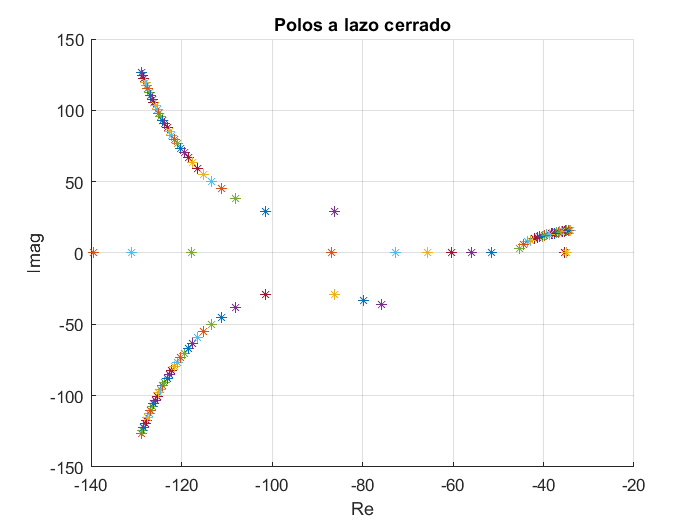

VOLTAGE_POLO = 102×2 table
    VOLTAGE         POLO      
    _______    _______________

     93.5      -128.87+126.69i
     93.5      -128.87-126.69i
     93.5      -34.039+16.111i
     94.5       -128.6+124.36i
     94.5       -128.6-124.36i
     94.5      -34.305+15.969i
     95.5      -128.33+122.04i
     95.5      -128.33-122.04i
     95.5      -34.578+15.819i
     96.5      -128.05+119.7i 
     96.5      -128.05-119.7i 
     96.5       -34.86+15.662i
     97.5      -127.76+117.37i
     97.5      -127.76-117.37i
     97.5      -35.151+15.498i
     98.5      -127.45+115.02i


% definimos la variable compleja s
syms s K M R G L V X1 X2 X3 % X mayuscula es para el punto de equilibrio; c = constante; m = masa ; R = resistencia; L = inductancia; V = tensión; g = gravedad

% Creacion de las matrices
In =  [1 0 0;0 1 0;0 0 1]
A = [0 1 0; (K*X3^2)/(M*X1^2) 0 (-2*K*X3)/(M*X1);0 0 -R/L]
B = [0;0;1/L]
C = [1 0 0]

% Funcion de transferencia 
H = C*inv(s*In - A)*B

%Puntos de equilibrio
x1 = (K*V^2)/(M*G*R^2)
x2 = 0
x3 = V/R


% Se sustituyeron los valores netos de
% http://dx.doi.org/10.1080/00207729608929322 

%Seleccion de Variables contantes
g = 9.81;
r = 27.7;
l = 0.65;
k = 1.24*10^-4;
m = 11.87*10^-3;

%Seleccion de variables inciertas
v1 = 110*0.85
v2 = 110*1.15

%Sustitucion de valores
Aq = subs(A, [X1 X3], [x1 x3])
Aqq= subs(Aq, [G M R K L],[g m r k l])
Aqq = [0 -C; [0; 0; 0] Aqq]
B=[0; B]
B= subs(B, L, l)


q1=Aqq(3,2)
q2=Aqq(3,4)
q3=Aqq(4,4)
q4=B(4,1)


% La variación en el tiempo de q1 y q2 en el tiempo sera de un 5% arriba y
% hacia abajo (definición del politopo)

%q4 pertenece a:


figure
for  v=v1:1:v2
    q1V = subs(q1, V, v);
    q2V = subs(q2, V, v);
    Aqqq=[0 1 0; q1V 0 q2V; 0 0 q3];
    p=eig(Aqqq);
    hold on
    plot(real(p(1)),imag(p(1)),'*')
    plot(real(p(2)),imag(p(2)),'*')
    plot(real(p(3)), imag(p(3)), '*')
end
grid
xlabel('Re'), ylabel('Imag'), title('Polos a lazo abierto')
hold off


% % Dibujamos la linea
q1i=[];
q2i=[];
for a=v1:0.1:v2
    q1i=[q1i subs(q1,V,a)];
    q2i=[q2i subs(q2,V,a)];
end

plot(q1i,q2i);title('q1 vs q2'); xlabel('q1');ylabel('q2');

%% Creamos la desigualdad lineal matricial 
% 
% 
% Realimentación de estado + reubicación de polos en región R(Alfa,Ro) 
% Theta = 0.

% Planta
A1=subs(Aqq, V, v1)

A2=subs(Aqq, V, v2)



% fi = fopen('alfaRoCasoTension.txt', 'a');

% for a=0:1:10
%     for b=0:1:45
%         if(~a<b)
            
            % Especificaciones región reubicación de polos
            Alfa=30;
            Ro=400;
            
            % Creación sistema LMI
            setlmis([])
            
            % Variables LMIs
            S=lmivar(1,[4 1]); % S(4,4) simétrica, 4x4 porque A es de 4x4 
            R=lmivar(2,[1 4]); % R(1,2) arbitraria, 1x4 porque B es de 1x4
            
            % S > 0
            
            lmiterm([-1 1 1 S],1,1);
            
            % Restricciones asociadas al parámetro Alfa
         
            % 𝑨𝑺 + 𝑺𝑨𝑻 + 𝑩1S + 𝑹𝑩1 + 𝟐𝜶𝑺 < 𝟎
            lmiterm([2 1 1 S],A1,1,'s');
            lmiterm([2 1 1 R],B,1,'s');
            lmiterm([2 1 1 S],2*Alfa,1);
            
            % 𝑨𝑺 + 𝑺𝑨𝑻 + 𝑩2R + 𝑹𝑩2 + 𝟐𝜶𝑺 < 𝟎
            lmiterm([3 1 1 S],A2,1,'s');
            lmiterm([3 1 1 R],B,1,'s');
            lmiterm([3 1 1 S],2*Alfa,1);
            
            
            % Restricciones asociadas al parámetro Ro
            
            % (A,B1)
            lmiterm([4 1 1 S],-Ro,1);
            lmiterm([4 1 2 S],A1,1);
            lmiterm([4 1 2 R],B,1);
            lmiterm([4 2 2 S],-Ro,1);
            
            % (A,B2)
            lmiterm([5 1 1 S],-Ro,1);
            lmiterm([5 1 2 S],A2,1);
            lmiterm([5 1 2 R],B,1);
            lmiterm([5 2 2 S],-Ro,1);
            
            
            % Ejecución del solver
            LMISYS=getlmis;
            [tmin,xfeas]=feasp(LMISYS);
          
            % Solución
            S=dec2mat(LMISYS,xfeas,S);
            R=dec2mat(LMISYS,xfeas,R);
            
            K=R*inv(S)
            
%             if(tmin<0) && (abs(K(1))<1)
%               K(1)
%              a
%              b
%              fprintf(fi, '%d %d \n',a, b);
%             end
%         end
%     end
% end

% fclose(fi);



% Polos a lazo cerrado del sistema  politópico

% Array que guarda los polos
POLO = [];
% Array que guarda la tensión 
VOLTAGE = [];

figure
for  v=v1:1:v2
    q1F = subs(q1, V, v);
    q2F = subs(q2, V, v);
    A=[0 -1 0 0; 0 0 1 0; 0 q1F 0 q2F; 0 0 0 q3];
    p=eig(A + B*K);
    VOLTAGE=[VOLTAGE; v; v ;v];
    POLO=[POLO;double(vpa(p(1),2)); double(vpa(p(2),2)); double(vpa(p(3), 2))];
    hold on
    plot(real(p(1)),imag(p(1)),'*')
    plot(real(p(2)),imag(p(2)),'*')
    plot(real(p(3)), imag(p(3)), '*')
end
grid
xlabel('Re'), ylabel('Imag'), title('Polos a lazo cerrado')
hold off


% Creamo una tabla en la cual se pueda ver la relación de tensión con cada
% polo 

VOLTAGE_POLO = table(VOLTAGE, POLO)

